# Inverted pendulum on a cart

## Physical model:

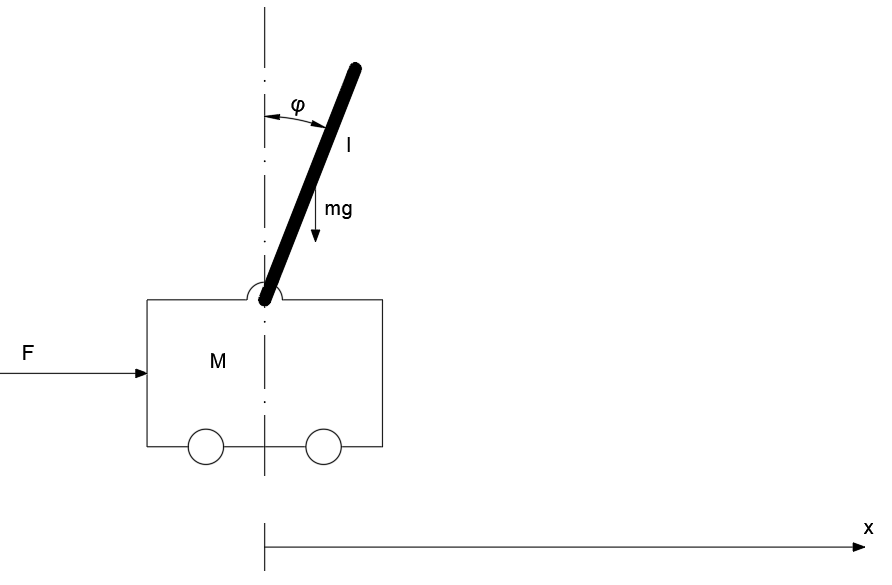


$$\ddot{x} =\frac{1}{\left(M+m\right)}F-\frac{b}{\left(M+m\right)}\dot{x} +\frac{m\;l}{\left(M+m\right)}{\dot{\varphi} }^2 \sin \left(\varphi \right)-\frac{m\;l}{\left(M+m\right)}\ddot{\varphi} \;\cos \left(\varphi \right)$$



$$\ddot{\varphi} =\frac{m\;g\;l}{\left(I+{m\;l}^2 \right)}\sin \left(\varphi \right)-\frac{m\;l}{\left(I+m\;l^2 \right)}\ddot{x} \;\cos \left(\varphi \right)$$


## Parameter initialization:

clear;
clc;

m = 0.1;
M = 0.3;
l = 0.6;
I = 0.006;
b = 0.01;
g = 9.81;

## Natural system response for initial condisions:

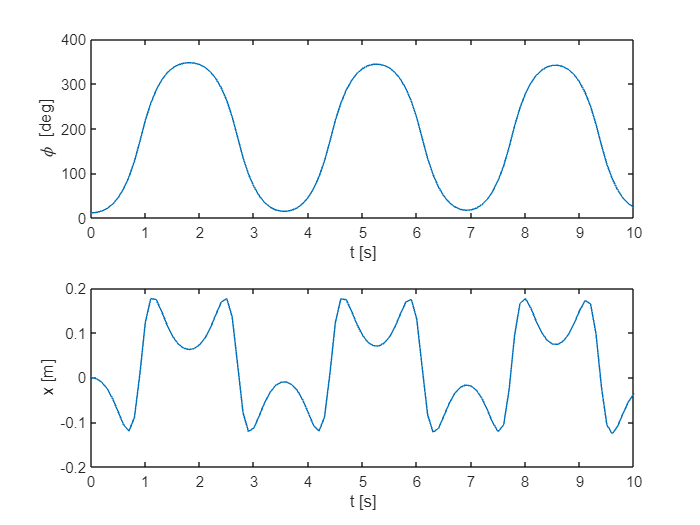

tspan = 0:0.1:10;   % Simulation time vector
y0 = [0,0,0.2,0];   % Initial conditions

[t,y] = ode45(@(t,y)pendulum(y,m,M,I,l,g,b,0),tspan,y0);

deg = y(:,3).*(180/pi);

subplot(2,1,1)
plot(t,deg)
xlabel('t [s]')
ylabel('\phi [deg]')
subplot(2,1,2)
plot(t,y(:,1))
xlabel('t [s]');
ylabel('x [m]')

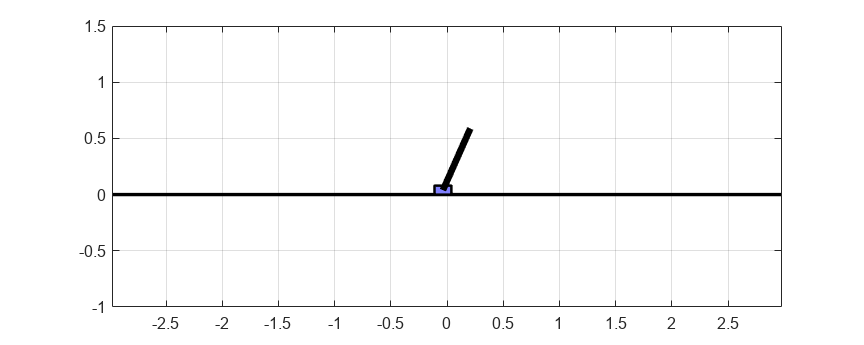

close
for i=1:length(t)
    pendulum_anim(y(i,:),l,0.15,0.08)
end

## Linearyzation around point $\varphi =0$


$$\sin \left(\varphi \right)\approx \varphi ,\;\cos \left(\varphi \right)\approx 1,\;{\dot{\varphi} }^2 =0,\;I=0$$



$$\bar{x} =\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
\varphi \\
\dot{\varphi} 
\end{array}\right\rbrack$$
       
$$\underline{\dot{x} } =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & -\frac{b}{M} & -\frac{\textrm{mg}}{M} & 0\\
0 & 0 & 0 & 1\\
0 & \frac{b}{\textrm{Ml}} & \frac{\left(M+m\right)g}{\textrm{Ml}} & 0
\end{array}\right\rbrack \bar{x} +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}\\
0\\
-\frac{1}{\textrm{Ml}}
\end{array}\right\rbrack u$$



$$y=\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
\varphi \\
\dot{\varphi} 
\end{array}\right\rbrack$$
       
$$y=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \bar{x}$$


A = [0,1,0,0;
     0,-b/M,-(m*g)/M,0;
     0,0,0,1;
     0,b/(M*l),(M+m)*g/(M*l),0];

B = [0,1/m,0,-1/M*l]';

C = [1,0,0,0;
     0,1,0,0;
     0,0,1,0;
     0,0,0,1];

D = 0;

linearsys = ss(A,B,C,D);

## Control using pole placement:

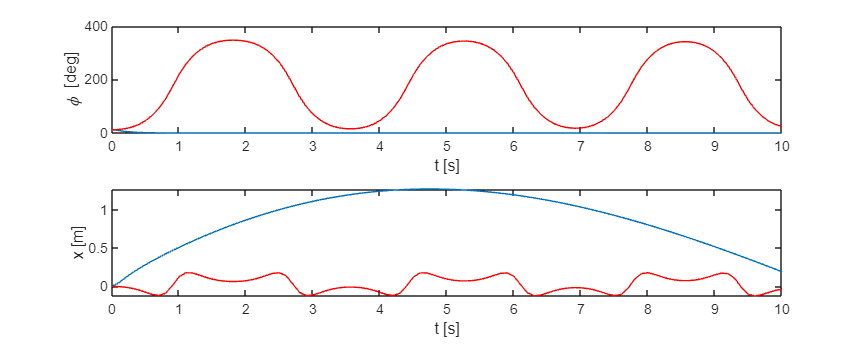

p = [-2,-2.1,-2.2,-2.3];    % New pole position vector
K = place(A,B,p);           % Feedback loop gain matrix
r = [-1,0,0,0]';             % Refrence (input) signal vector

[tr,yr] = ode45(@(tr,yr)pendulum(yr,m,M,I,l,g,b,-K*(yr-r)),tspan,y0);

deg = y(:,3).*(180/pi);
degr = yr(:,3)*(180/pi);

subplot(2,1,1)
plot(tr,degr,t,deg,'r')
xlabel('t [s]')
ylabel('\phi [deg]')
subplot(2,1,2)
plot(tr,yr(:,1),t,y(:,1),'r')
xlabel('t [s]');
ylabel('x [m]')

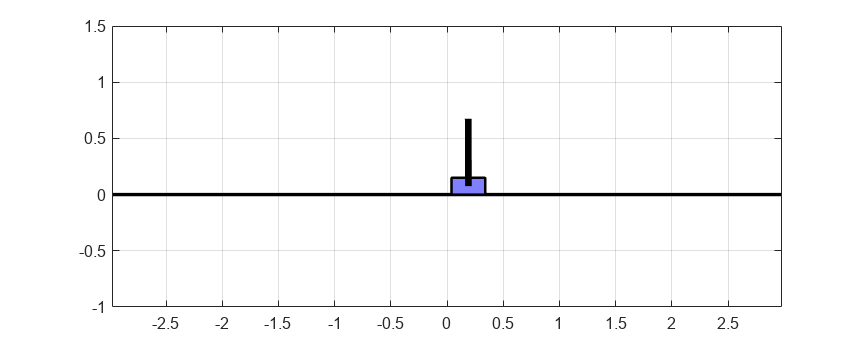

close
for i=1:length(tr)
    pendulum_anim(yr(i,:),l,0.3,0.15)
end

## LQR:

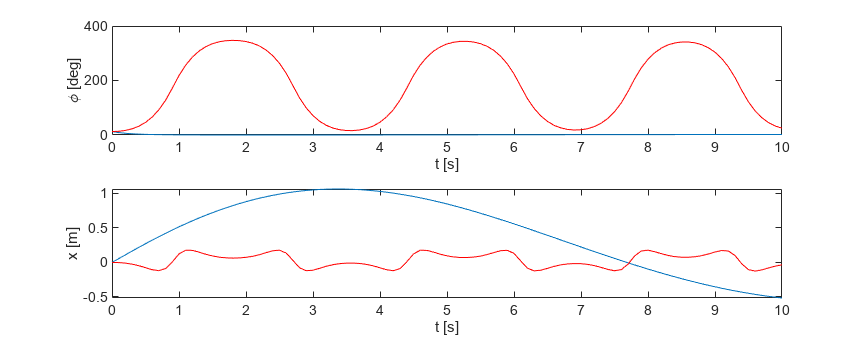

Q = [1,0,0,0;
     0,0.1,0,0;
     0,0,10,0;
     0,0,0,100];

R = 0.01;

K = lqr(A,B,Q,R);
r = [0,0,0,0]';

[tr,yr] = ode45(@(tr,yr)pendulum(yr,m,M,I,l,g,b,-K*(yr-r)),tspan,y0);

deg = y(:,3).*(180/pi);
degr = yr(:,3)*(180/pi);

subplot(2,1,1)
plot(tr,degr,t,deg,'r')
xlabel('t [s]')
ylabel('\phi [deg]')
subplot(2,1,2)
plot(tr,yr(:,1),t,y(:,1),'r')
xlabel('t [s]');
ylabel('x [m]')

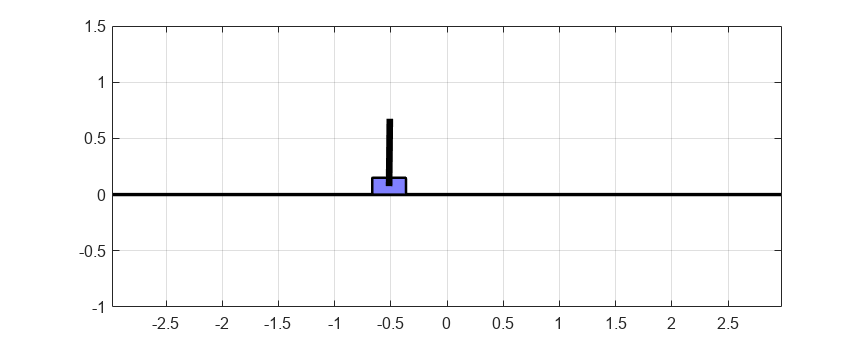

close
for i=1:length(tr)
    pendulum_anim(yr(i,:),l,0.3,0.15)
end